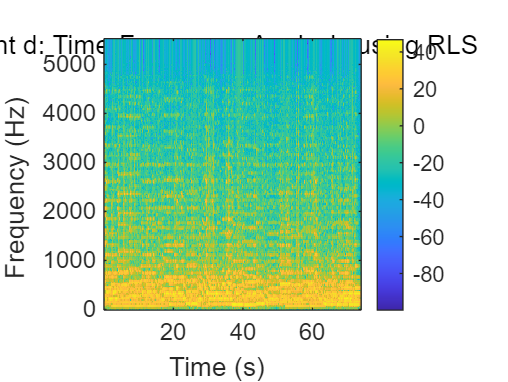

%%%%%%%%%%%  Hw2 - point d: RLS denoise %%%%%%%%
clear all;
close all;
clc;

Sin = load('Hw2d.mat'); 
load('Sn_ref_d1.mat');

fs = Sin.fs;
sin_frame_d = Sin.Sin_d;     
sn_ref_d = sn_ref_matirx;  
sin_d = sin_frame_d(:, 1);         
sn_ref_d1 = sn_ref_d(:, 1);   
sn_ref_d2 = sn_ref_d(:, 2);   

%RLS
K_o = 10;       

mu = 0.9;     
num_samples = length(sin_d);  

lambda = 0.999;% 遗忘因子
delta = 1e-6;                
W = zeros(K_o, 1);%滤波器权重
R = delta * eye(K_o); %协方差矩阵 


s_est_d = zeros(num_samples, 1);

for k = 1:num_samples
    sn_ref_frame = sn_ref_d(:, k);     
    %增益向量
    K = (R * sn_ref_frame) / (lambda + sn_ref_frame' * R * sn_ref_frame);
    %误差信号
    ERROR = sin_d(k) - W' * sn_ref_frame;
    W = W + K * ERROR;


    %更新协方差矩阵
    R = (1 / lambda) * (R - K * sn_ref_frame' * R);
    %估计信号
    s_est_d(k) = ERROR;  
end

N = 400; %FFT 变换窗口大小
L = N / 2;
window = hamming(N); 

figure('Name','原始信号谱图','NumberTitle','off');
[S1, F1, T1] = spectrogram(sin_d, window, L, N, fs);
imagesc(T1, F1, 20 * log10(abs(S1)));
axis xy;
xlabel('Time (s)'); ylabel('Frequency (Hz)');
title('Point d: Time-Frequency Analysis of Signals mixed with noise');
colorbar;


figure('Name','RLS处理后谱图','NumberTitle','off');
[S2, F2, T2] = spectrogram(s_est_d, window, L, N, fs);
imagesc(T2, F2, 20 * log10(abs(S2)));
axis xy;
xlabel('Time (s)'); ylabel('Frequency (Hz)');
title('Point d: Time-Frequency Analysis using RLS');
colorbar;

disp([min(s_est_d), max(s_est_d), mean(s_est_d)]);

   -4.3145    4.0383    0.0007




% ====== 确保图像刷新后再播放 ======
sound(s_est_d, fs);
pause(length(s_est_d)/fs + 0.5);






